clc,clear
load('armaxdata.mat')

traindata_u = u(1:height(u)-33333);
traindata_y = y(1:height(y)-33333);
valdata_u = u(height(u)-33333:height(u));
valdata_y = y(height(y)-33333:height(y));

traindata = iddata(traindata_y, traindata_u);
valdata = iddata(valdata_y, valdata_u);

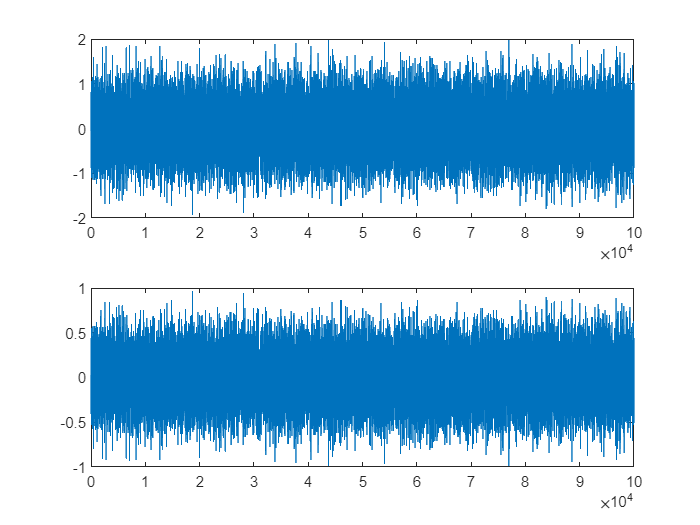

% look at data

subplot(211)
plot(u)
subplot(212)
plot(y)

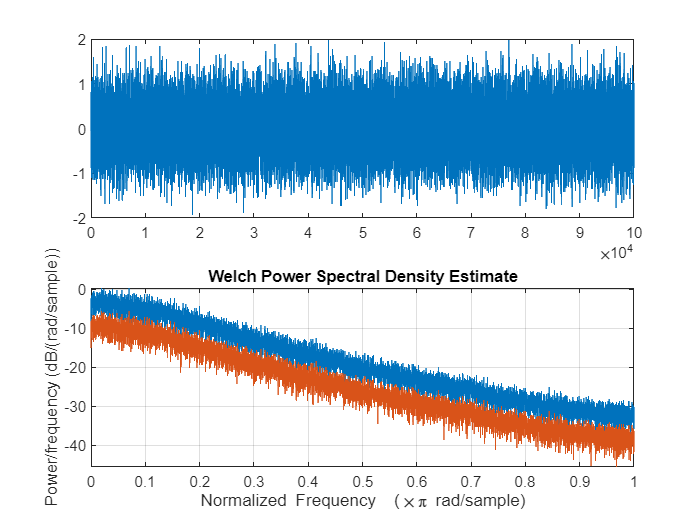

% plot welch spectrum
pwelch(u), hold on
pwelch(y)

**Assignment 2. a)**

The ARMAX model is A(q)y(t)=B(q)u(t)+C(q)e(t) and the orders as provided by the assignment are na = 2, nb = 1, nc = 1.

Simulating the model gives:

[1 a1 a2] =[1 -1.13e-18 2.74e-19]

b = [-0.5]

[1 c] = [1 2.74e-0.4] 

Performance analysis states that the estimation is valid, as comparing to validation data gives 100% match and residuals are within confidence.

model = armax(traindata, [2 1 1 0])

model =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 1.132e-18 z^-1 + 2.745e-19 z^-2             
                                                         
  B(z) = -0.5                                            
                                                         
  C(z) = 1 + 0.0002743 z^-1                              
                                                         
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=2   nb=1   nc=1   nk=0
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                               
Estimated using ARMAX on time domain data "traindata".
Fit to estimation data: 100% (prediction focus)       
FPE: 8.823e-41, MSE: 8.822e-41                        


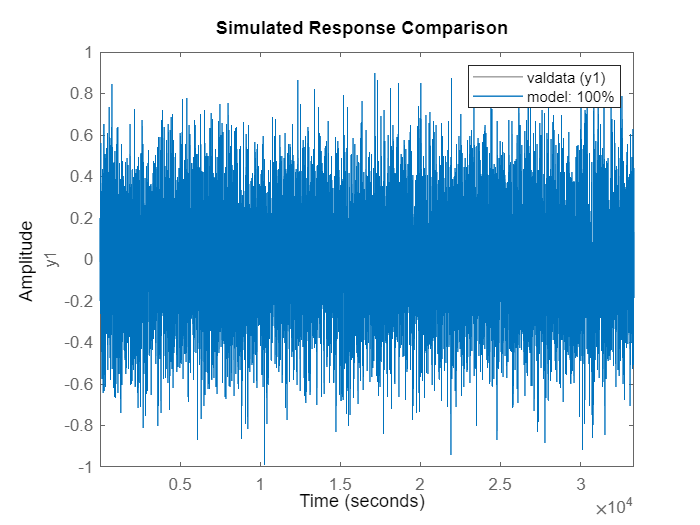

% Performance analysis

figure
horizon = inf;
compare(valdata,model,horizon)

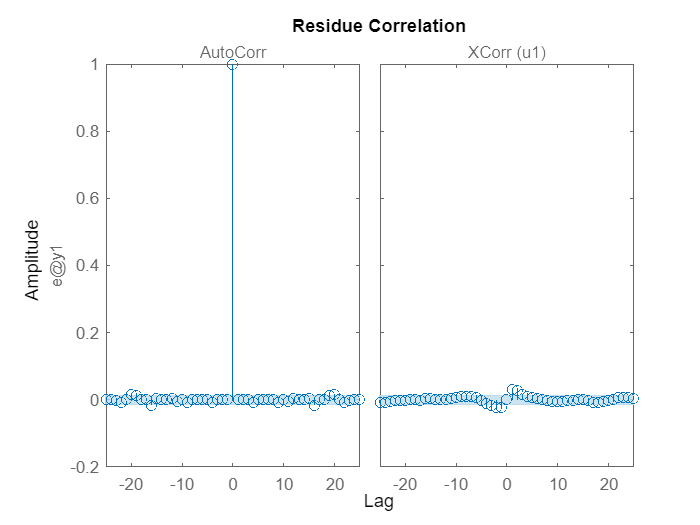

resid(valdata,model)

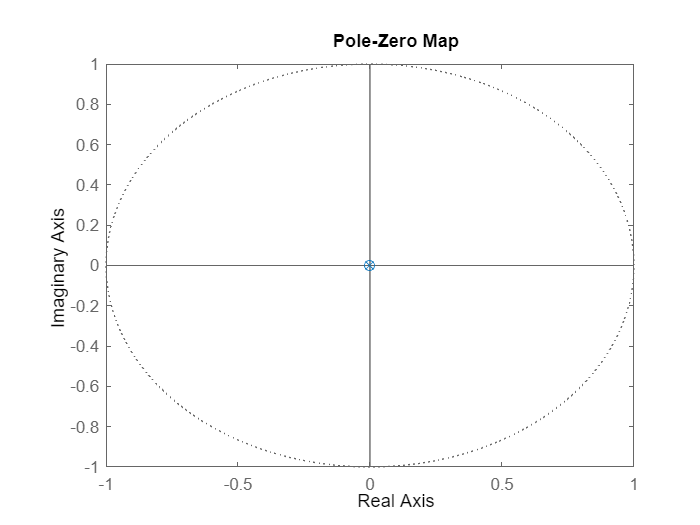

pzmap(model)

**Assignment 2. b)**

The covariance matrix states close to zero values for all parameters, showing that there is a redundancy of parameter estimation.

covMatrix = getcov(model);

param_std = sqrt(diag(covMatrix));
disp('Covariance matrix of parameters:');

Covariance matrix of parameters:


disp(covMatrix);

   1.0e-04 *

    0.0000   -0.0000   -0.0000    0.0000
   -0.0000    0.0000    0.0000   -0.0000
   -0.0000    0.0000    0.0000    0.0000
    0.0000   -0.0000    0.0000    0.1507



disp('Standard deviations of parameters:');

Standard deviations of parameters:


disp(param_std);

    0.0000
    0.0000
    0.0000
    0.0039



**Assignment 2. c)**

By interpreting d as a transfer function according to u(k)=dy(k), the transfer function d can be calculated using spectral estimates. The resulting step response and bode diagram shows that the function d essentially lowers the input by 2, and the bode diagram shows that all frequencies gets lowered by 6dB and phase shifted by 180 degrees. There is no significant processing occuring to the general shape of the signal, that's why the covariance matrix of several orders in b) was shown as redundant. This also explains the plots from a) showing inputs and outputs being highly similar. The comparison from before is also explained as being true, as the modelling process is just a function of phase shift and magnitude estimation.

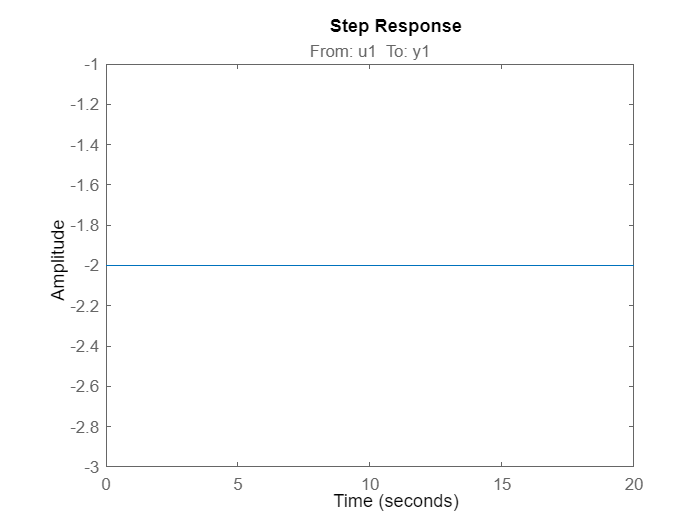

gamma = 3;
w = 0:pi;
Ghat = spa(iddata(u,y),gamma,w);
step(Ghat)

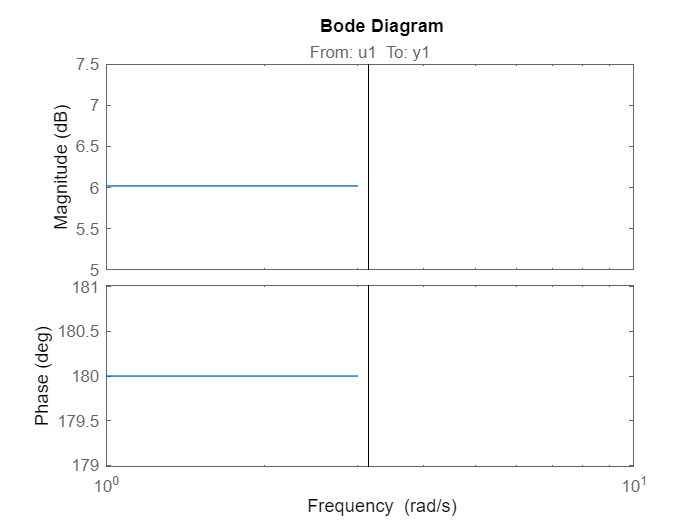

bode(Ghat)

**Assignment 2. d)**

model = armax(traindata,[1 1 0 0]);

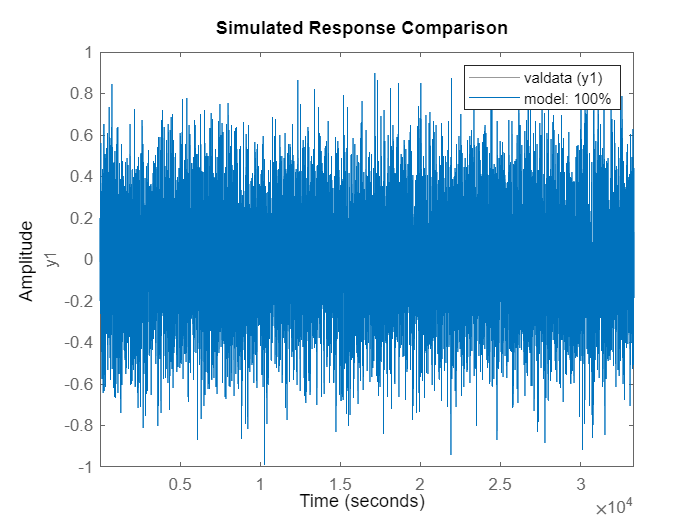

% Performance analysis
figure
horizon = inf;
compare(valdata,model,horizon)

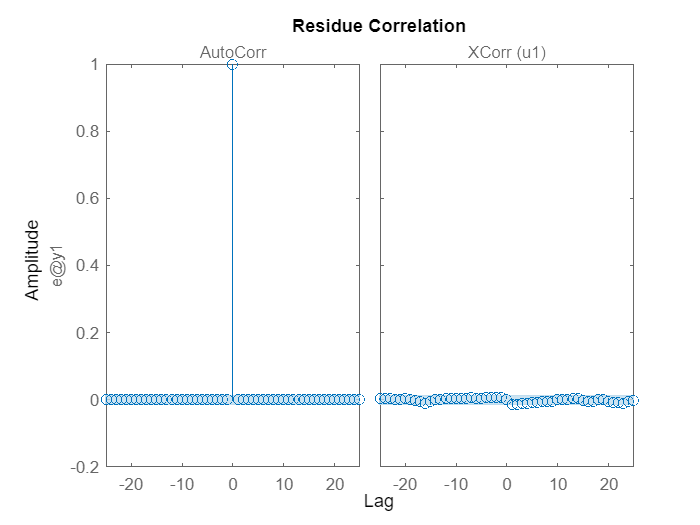

resid(valdata,model)

pzmap(model)